clc; close all; clear variables
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');set(groot,'defaulttextinterpreter','latex');  

## **DYNAMICS AND CONTROL OF VEHICLES AND ROBOTS**

## Intro

In this script the telemetry data from the P1 experimental vehicles are loaded. This Matlab Live Script can be used as the structure for your project script. 

Click "Save as..." and save this script as .m in order to obtain a classic Matlab script.

## Load Vehicle Parameters

The script loads the vehicle main parameters in the `vehicle` struct. See the script `p1_parameters.m` for comments about parameters names and units.

p1_parameters

## Load Datasets

The following test are available.

**DATASET NAME DESCRIPTION**

RAMP_STEER_L Left-hand ramp steer 10 m/s

RAMP_STEER_R Right-hand ramp steer 10 m/s

SINE_STEER_IS Sine wave steering at increasing speeds

SP_100FT_CR_IS_CCW Steering pad 100 ft circle constant radius increasing speed counter-clockwise

SP_100FT_CR_IS_CW Steering pad 100 ft circle constant radius increasing speed clockwise

STRAIGHT_LINE_0 Straight line at constant speed

STRAIGHT_LINE_1 Straight line in one direction

STRAIGHT_LINE_2 Straight line in the opposite direction

STEP_STEER Step steer

The loaded variable is a struct cointaing the following telemetry signals:

% DATA			UNITS		DESCRIPTION
% time                  s               acquisition time
% yaw			rad		yaw angle
% yaw_rate		rad/s 		yaw rate at COM
% roll			rad		roll at COM
% roll_rate		rad/s 		roll rate at COM
% long_vel		m/s 		longitudinal velocity of the COM
% lat_vel		m/s 		lateral velocity of the COM
% axG			m/s^2		longitudinal acceleration of the COM
% ayG			m/s^2 		lateral acceleration of the COM
% body_slip		rad		vehicle side slip angle (at COM)
% omega_FL		rad/s 		wheel angular speed
% omega_FR		rad/s 		wheel angular speed
% omega_RL		rad/s 		wheel angular speed
% omega_RR		rad/s 		wheel angular speed
% front_slip_angle      rad		equivalent (single track) slip angle at front axle
% rear_slip_angle       rad		equivalent (single track) slip angle at rear axle
% Fx_FL			N		tyre longitudinal force
% Fy_FL			N		tyre lateral force
% Fz_FL			N		tyre vertical force
% Fx_FR			N		tyre longitudinal force
% Fy_FR			N		tyre lateral force
% Fz_FR			N		tyre vertical force
% x_pos			m		COM position x coordinate (from GPS)
% y_pos			m		COM position y coordinate (from GPS)
% z_pos			m		COM position z coordinate or altitude (from GPS)
% delta_L		rad		steering angle of the front left wheel
% delta_R		rad		steering angle of the front right wheel
% delta_HW 		rad		handwheel steering angle

## Steering Ratio Estimation

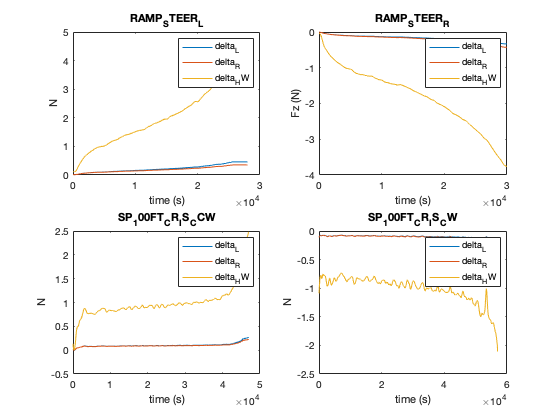


load("Dataset/RAMP_STEER_L.mat");
load("Dataset/RAMP_STEER_R.mat");
load("Dataset/SP_100FT_CR_IS_CCW.mat");
load("Dataset/SP_100FT_CR_IS_CW.mat");
load("roll_rad.mat","R_dyn")
%Check steering angles left-right
figure
subplot(2,2,1)
plot(smooth(RAMP_STEER_L.time,RAMP_STEER_L.delta_L,500),'DisplayName','delta_L')
hold on
plot(smooth(RAMP_STEER_L.time,RAMP_STEER_L.delta_R,500),'DisplayName','delta_R')
hold on
plot(smooth(RAMP_STEER_L.time,RAMP_STEER_L.delta_HW,500),'DisplayName','delta_HW')
xlabel('time (s)');ylabel('N');
title('RAMP_STEER_L');
legend

subplot(2,2,2)
plot(smooth(RAMP_STEER_R.time,RAMP_STEER_R.delta_L,500),'DisplayName','delta_L')
hold on
plot(smooth(RAMP_STEER_R.time,RAMP_STEER_R.delta_R,500),'DisplayName','delta_R')
hold on
plot(smooth(RAMP_STEER_R.time,RAMP_STEER_R.delta_HW,500),'DisplayName','delta_HW')
xlabel('time (s)');ylabel('Fz (N)');
title('RAMP_STEER_R');
legend

subplot(2,2,3)
plot(smooth(SP_100FT_CR_IS_CCW.time,SP_100FT_CR_IS_CCW.delta_L,500),'DisplayName','delta_L')
hold on
plot(smooth(SP_100FT_CR_IS_CCW.time,SP_100FT_CR_IS_CCW.delta_R,500),'DisplayName','delta_R')
hold on
plot(smooth(SP_100FT_CR_IS_CCW.time,SP_100FT_CR_IS_CCW.delta_HW,500),'DisplayName','delta_HW')
xlabel('time (s)');ylabel('N');
title('SP_100FT_CR_IS_CCW');
legend

subplot(2,2,4)
plot(smooth(SP_100FT_CR_IS_CW.time,SP_100FT_CR_IS_CW.delta_L,500),'DisplayName','delta_L')
hold on
plot(smooth(SP_100FT_CR_IS_CW.time,SP_100FT_CR_IS_CW.delta_R,500),'DisplayName','delta_R')
hold on
plot(smooth(SP_100FT_CR_IS_CW.time,SP_100FT_CR_IS_CW.delta_HW,500),'DisplayName','delta_HW')
xlabel('time (s)');ylabel('N');
title('SP_100FT_CR_IS_CW');
legend


ft = fittype('tau_s*delta_w'); 

Error using fittype>iDeduceCoefficients (line 621)
The independent variable x does not appear in the equation expression.
Use x in the expression or indicate another variable as the independent variable.

Error in fittype>iCreateCustomFittype (line 477)
    obj = iDeduceCoefficients(obj);

Error in 

fit_tau_FL_1 = fit(abs(mean([STRAIGHT_LINE_1.long_vel])),mean(STRAIGHT_LINE_1.long_vel-STRAIGHT_LINE_1.omega_FL*R_dyn),ft,'StartPoint',0);
kx_FL_1 = fit_kx_FL_1.Kx;
fit_kx_FR_1 = fit(abs(mean([STRAIGHT_LINE_1.long_vel])),mean(STRAIGHT_LINE_1.long_vel-STRAIGHT_LINE_1.omega_FR*R_dyn),ft,'StartPoint',0);
kx_FR_1 = fit_kx_FR_1.Kx;